clc
clear 
Ts = 1/5;
quad = Quad(Ts);
[xs, us] = quad.trim();
sys = quad.linearize(xs, us);
[sys_x, sys_y, sys_z, sys_yaw] = quad.decompose(sys, xs, us);

System loaded and decomposed to 4 parts.

Next, we design MPC controllers for each subsystem individually. For all controllers, optimization is done over a time horizon of 15. We tune the cost matrix Q to attain the desired settling time requirement. 

% Design MPC controllers
fprintf('\n\nTuning controllers...')



Tuning controllers...

fprintf('X direction:')

X direction:

mpc_x = MPC_Control_x(sys_x, Ts);

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...


fprintf('Y direction:')

Y direction:

mpc_y = MPC_Control_y(sys_y, Ts);

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...
Iteration 5...
Iteration 6...
Iteration 7...
Iteration 8...


fprintf('Z direction:')

Z direction:

mpc_z = MPC_Control_z(sys_z, Ts);

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 1...
Iteration 2...
Iteration 3...


fprintf('Yaw:\n')

Yaw:


mpc_yaw = MPC_Control_yaw(sys_yaw, Ts);

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...


Each subsystem is simulated until it converges,

% Simulating the closed-loop system
subsystems = ["x", "y", "z", "yaw"];    % subsystems names
tol = 1e-3;                             % convergence criterion
settling_time = zeros(4, 1);            % settling time of each subsystem

% simulate for each subsystem
for sys_num = 1:4
    fprintf(strcat('\nSimulating subsystem ', '\t', subsystems(sys_num)))
    
    % set initial condition
    switch sys_num                      % initial condition for angle
        case 3
            x0 = [0; 2];                % stationary at 2m above the origin
        case 4
            x0 = [0; deg2rad(45)];      % stationary at 45 degree
        otherwise
            x0 = [0; 0; 0; 2];          % stationary at 2m from the origin
    end
    clear sol
    sol.x(:,1) = x0;
    
    % select controller
    switch sys_num
        case 1
            mpc_cont = mpc_x;
        case 2
            mpc_cont = mpc_y;
        case 3
            mpc_cont = mpc_z;
        case 4
            mpc_cont = mpc_yaw;
        otherwise
            fprintf('[Error] subsystem number out of range.')
    end
    
    % simulate at each time step
    i = 1;
    try
        while norm(sol.x(:,end)) > tol  % Simulate until convergence
            % Solve MPC problem for current state
            uopt = mpc_cont.get_u(sol.x(:,i));   
            % Extract the optimal input
            sol.u(:,i) = uopt;
            % Apply the optimal input to the system
            sol.x(:,i+1) = mpc_cont.A*sol.x(:,i) + mpc_cont.B*sol.u(:,i);
            % Go to next time step
            i = i + 1;
        end
    catch
        error('---> Initial state is outside the feasible set <---\n');
    end
    
    % find settling time
    settled = prod(abs(sol.x)<=0.5, 1);     % settled[i] = 1 iff all states are settled at index i
    settled = find(settled);                % indexes when all states are settled
    settling_time(sys_num)=Ts*(settled(1)-1);% settling time in seconds
    fprintf(strcat('Settling time for this subsystem = ', num2str(settling_time(sys_num))));
    
    % save results
    switch sys_num
        case 1
            solution.x = sol;
        case 2
            solution.y = sol;
        case 3
            solution.z = sol;
        case 4
            solution.yaw = sol;
        otherwise
            fprintf('[Error] subsystem number out of range.');
    end
    clear sol
end


Simulating subsystem	x

Settling time for this subsystem =4


Simulating subsystem	y

Settling time for this subsystem =4


Simulating subsystem	z

Settling time for this subsystem =2


Simulating subsystem	yaw

Settling time for this subsystem =1.4


fprintf(strcat("\nMaximum settling time of all subsystems = ", {' '}, num2str(max(settling_time))));


Maximum settling time of all subsystems =  4

Plot the applied input and states.

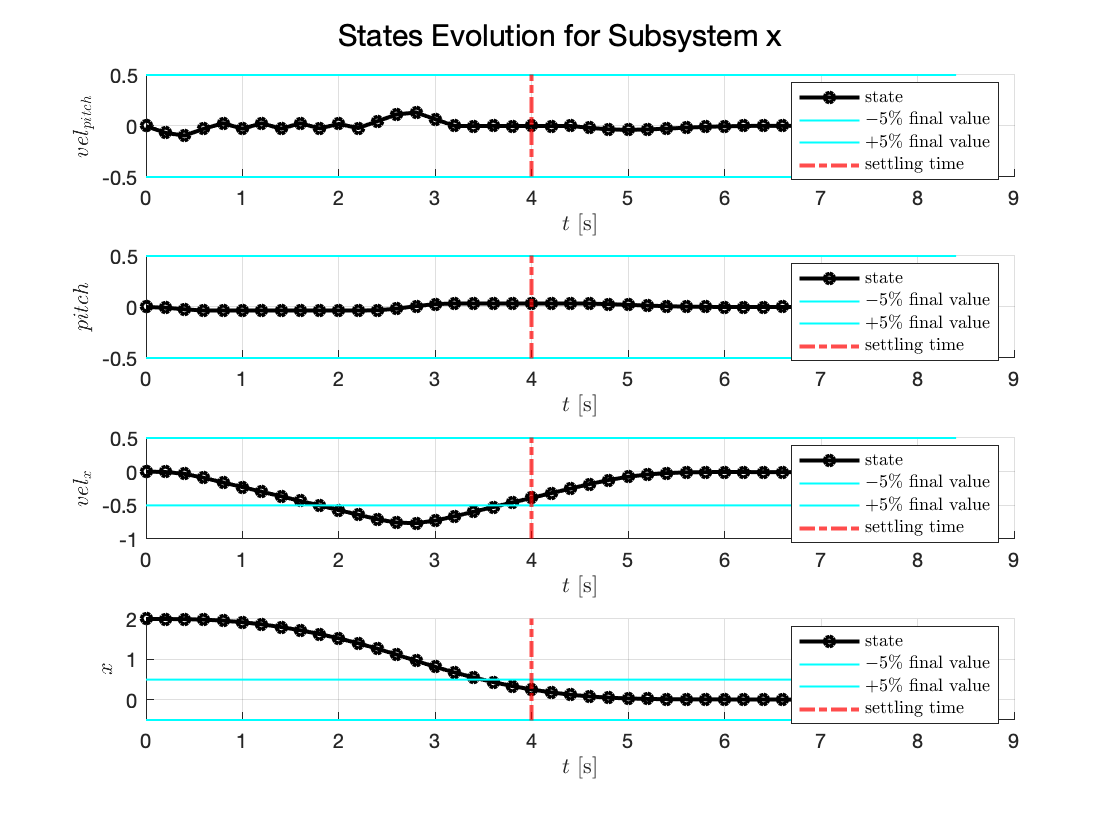

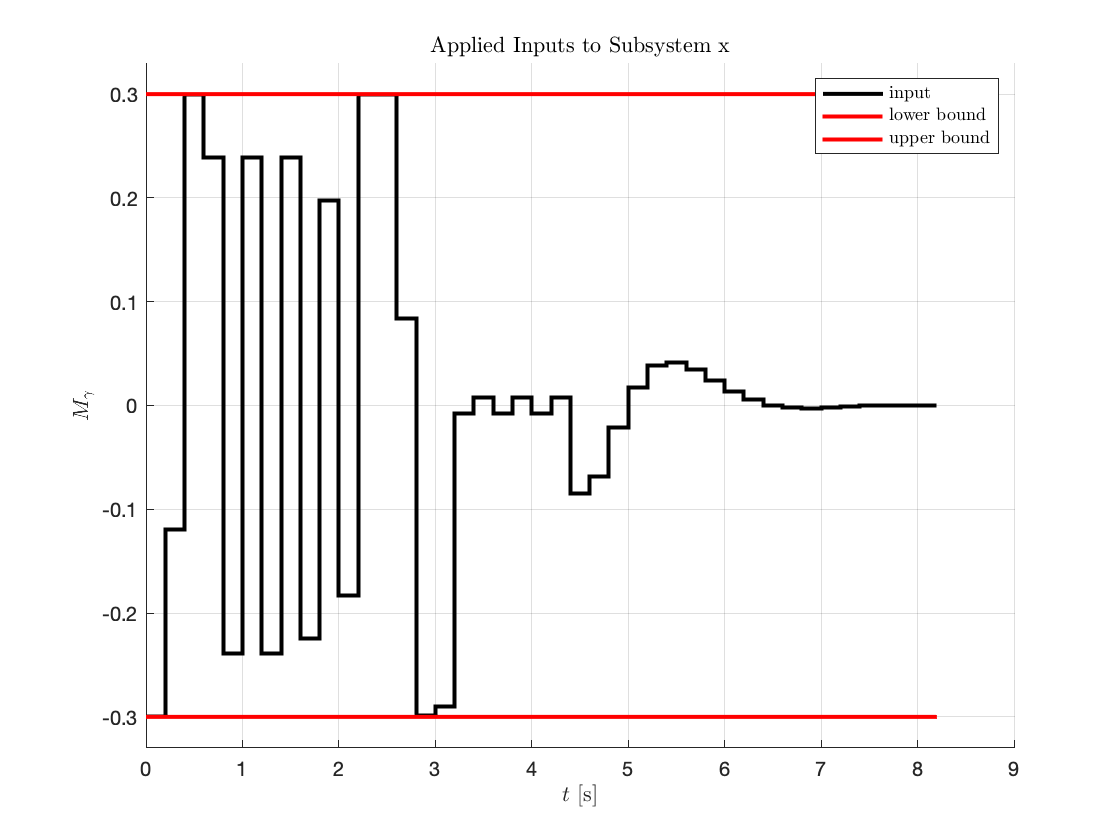

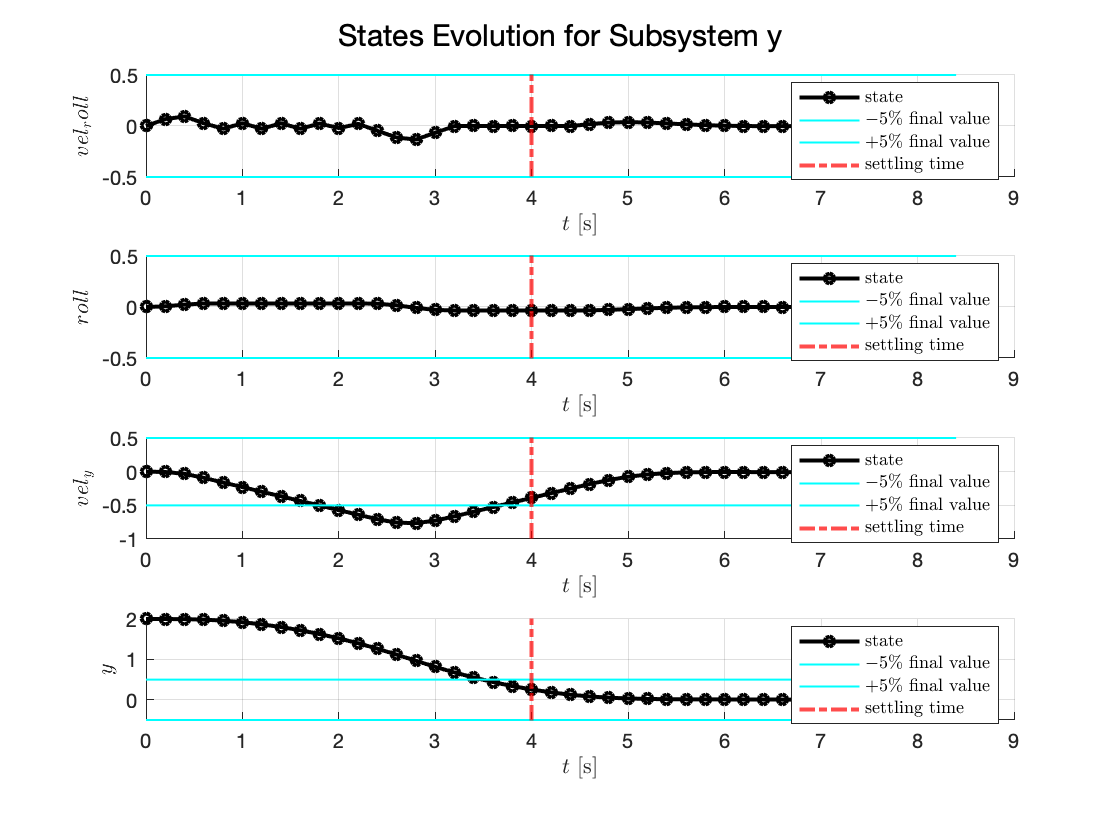

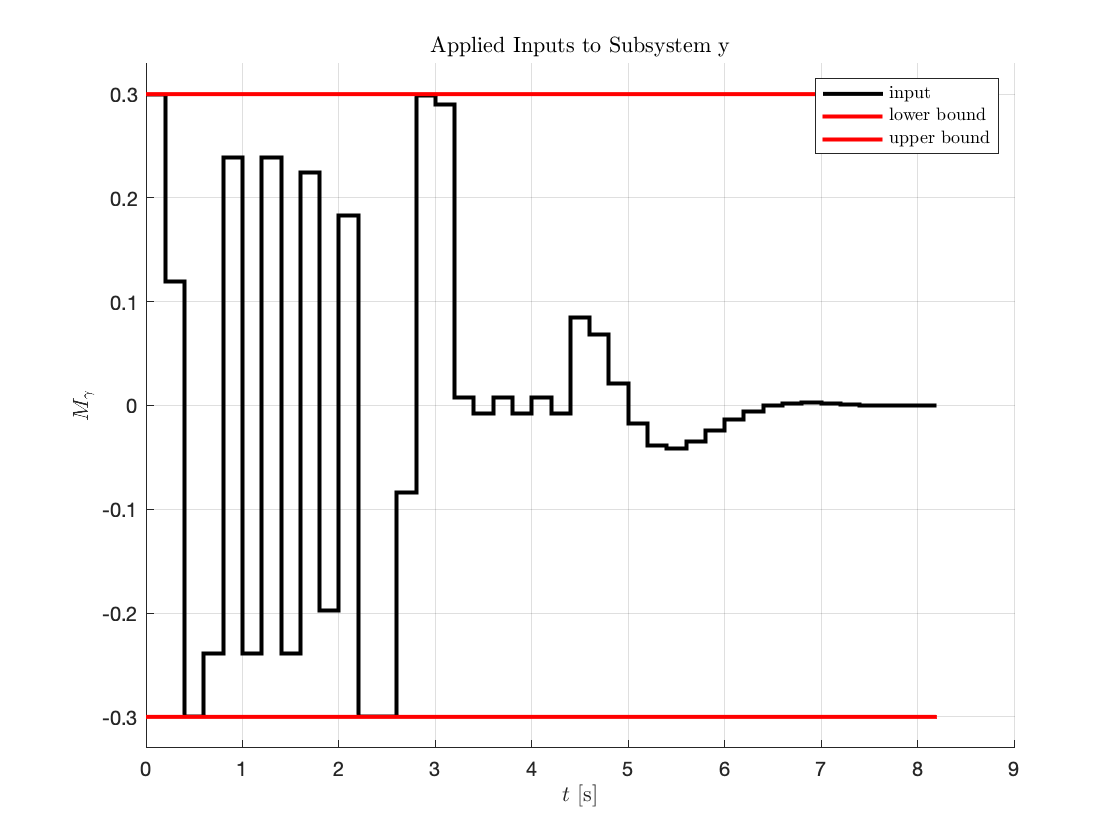

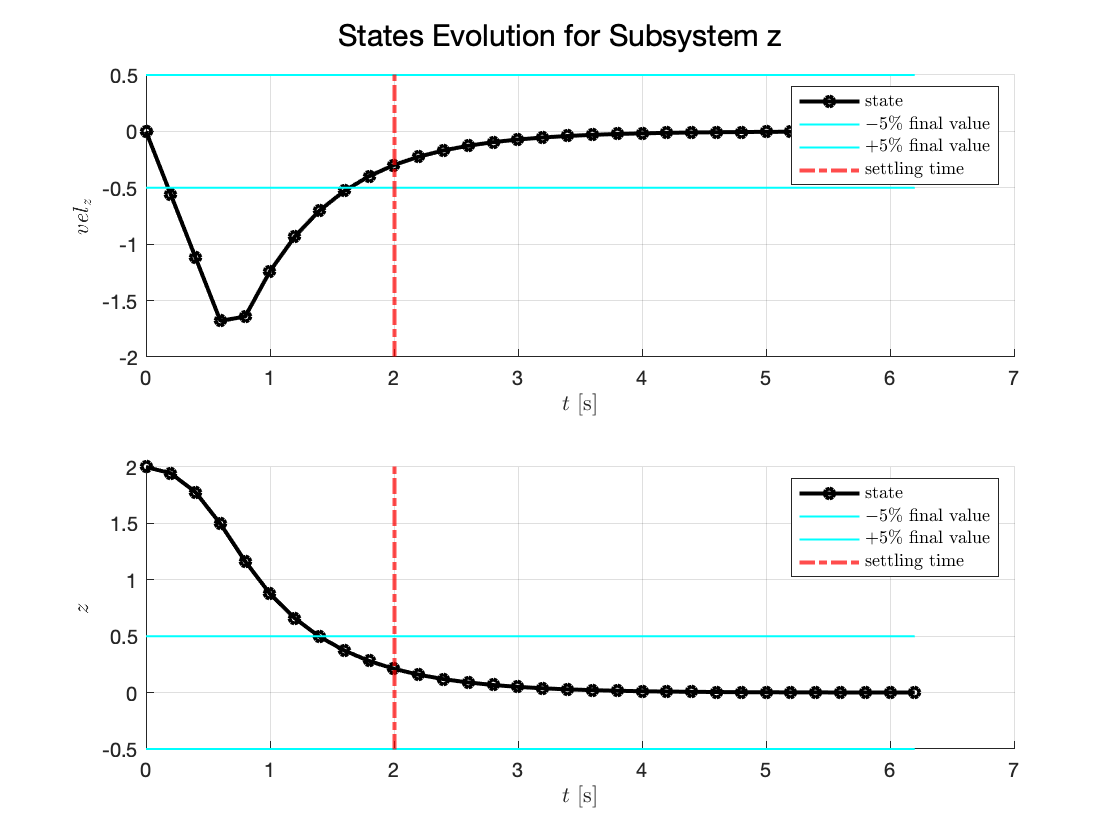

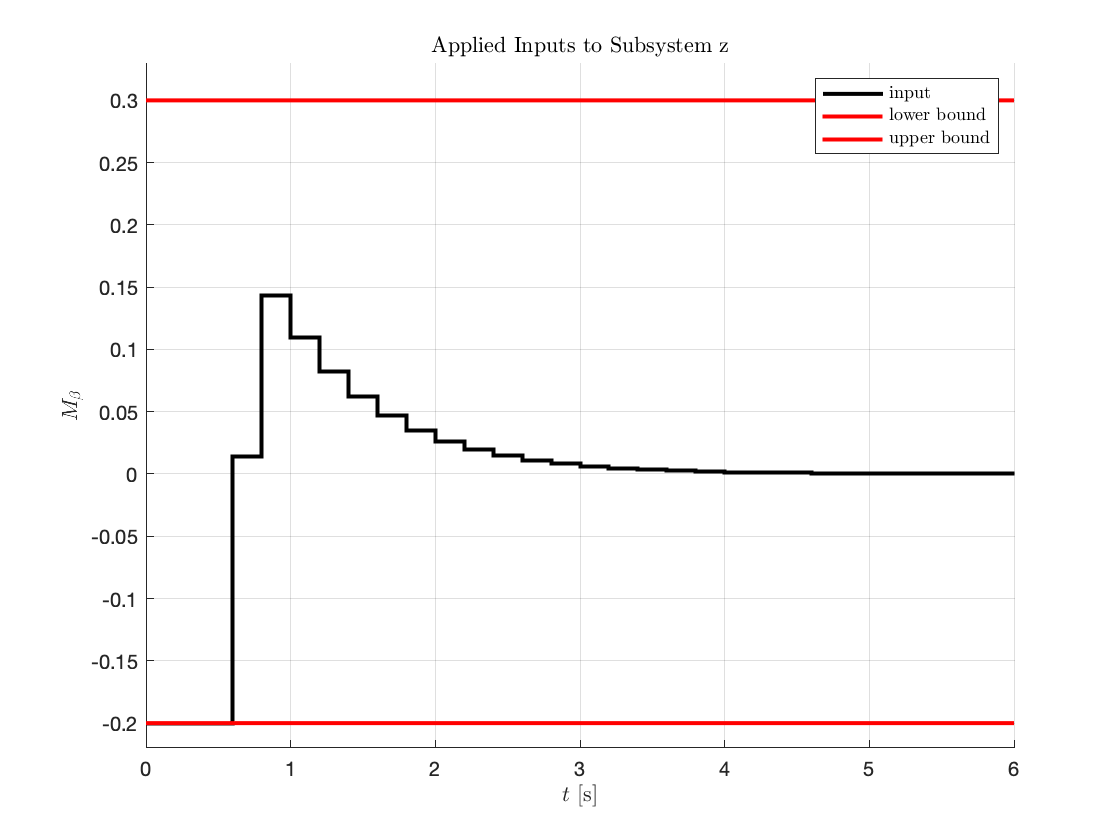

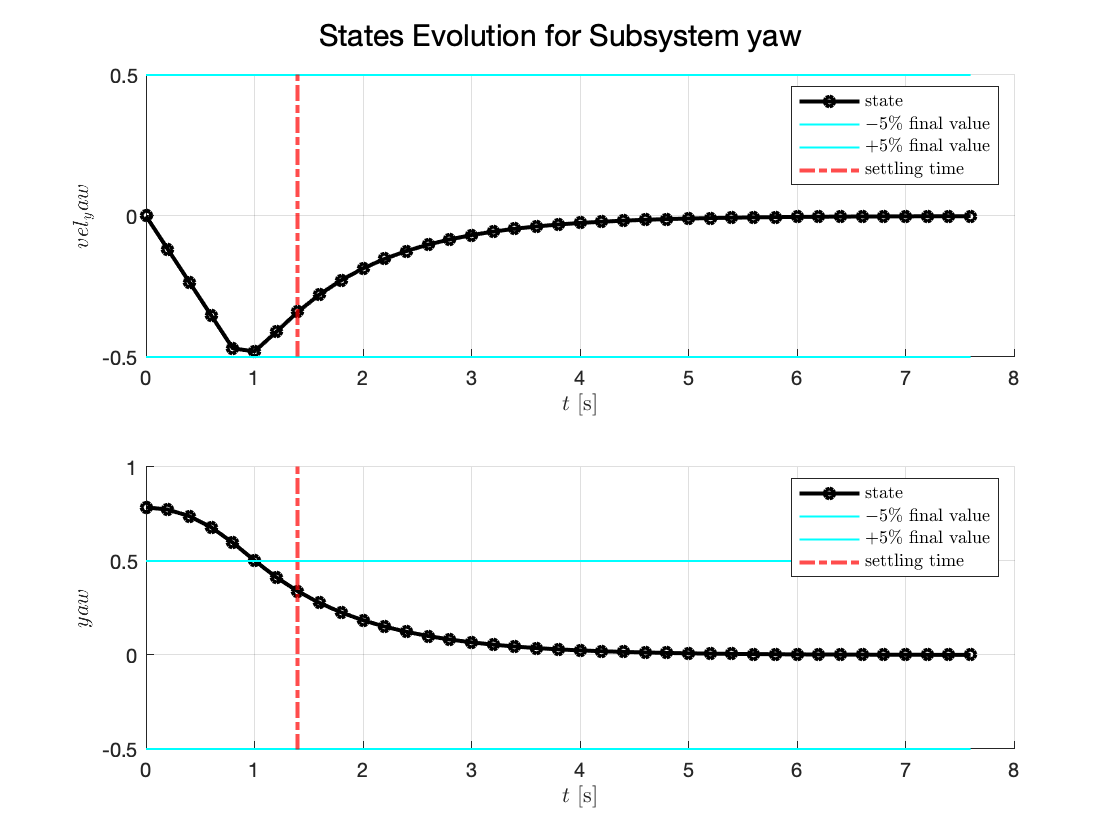

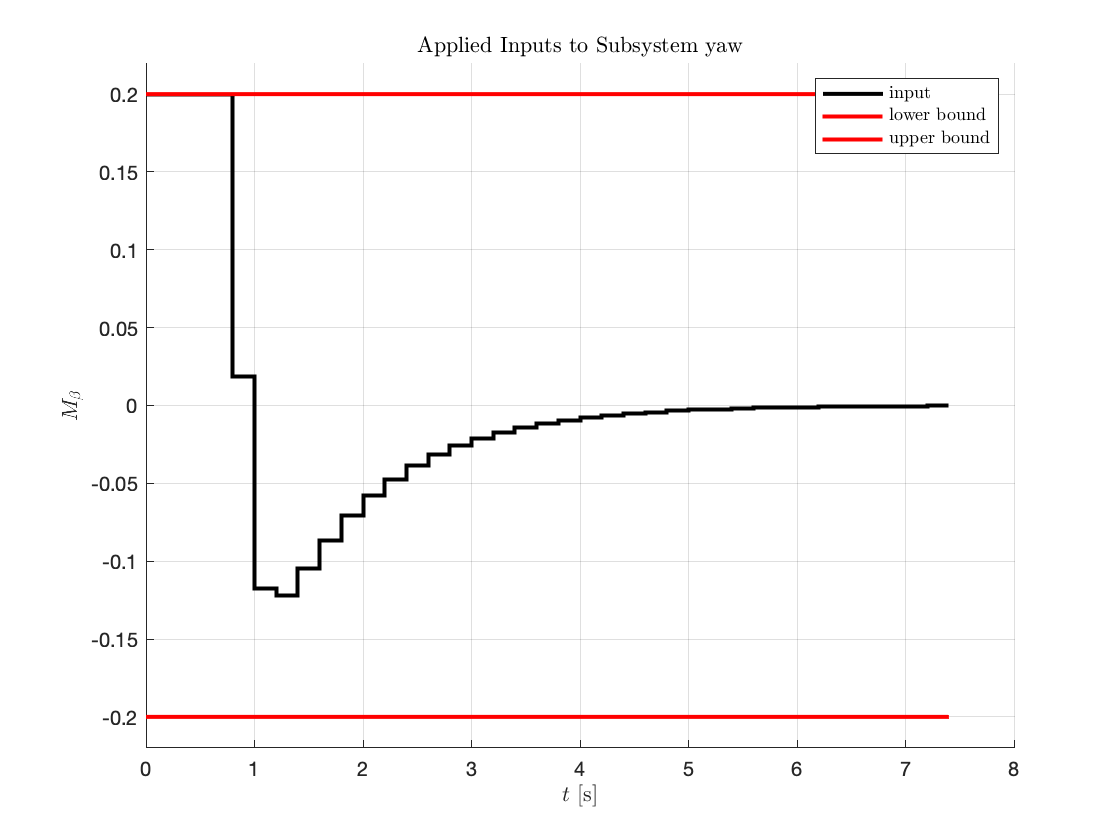

% define input names
input_names = ["$M_\alpha$", "$M_\beta$", "$F$", "$M_\gamma$"];
sys_x.StateName(1) = {'vel_{pitch}'};

% produce two figures for each subsystem
for sys_num = 1:4
    % retrive solution
    switch sys_num
        case 1
            sol = solution.x;
            subsys = sys_x;
            umin = -0.3; umax = 0.3;
        case 2
            sol = solution.y;
            subsys = sys_y;
            umin = -0.3; umax = 0.3;
        case 3
            sol = solution.z;
            subsys = sys_z;
            umin = -0.2; umax = 0.3;
        case 4
            sol = solution.yaw;
            subsys = sys_yaw;
            umin = -0.2; umax = 0.2;
        otherwise
            fprintf('[Error] subsystem number out of range.');
    end
    
    % solution properties
    num_states = size(sol.x, 1);
    num_sample = size(sol.x, 2);
    
    % constants
    times = 0: Ts: Ts * (num_sample-1);
    o = ones(1, num_sample);
    
    % produce figures for each state
    figure
    hold on; grid on;
    for fig_num = 1 : num_states
        subplot(num_states, 1, fig_num);
        hold on; grid on;
        plot(times, sol.x(fig_num, :),'-ok','markersize',5,'linewidth',2);
        plot(times, -0.5*o,'c','linewidth',1)
        plot(times, 0.5*o,'c','linewidth',1)
        xline(settling_time(sys_num), '-.r','linewidth',2) 
        legend('state', '$-5\%$ final value', '$+5\%$ final value', 'settling time' ,'Interpreter','latex') 
        ylabel(strcat("$", subsys.StateName(fig_num), "$") ,'Interpreter','latex');   
        xlabel('$t$ [s]','Interpreter','latex')
        hold off
    end
    sgtitle(strcat("States Evolution for Subsystem", {' '}, subsystems(sys_num)));
    
    % figure for input
    figure()
    hold on; grid on;
    stairs(times(1:end-1), sol.u,'k','markersize',20,'linewidth',2);
    plot(times(1:end-1), umin*o(1:end-1),'r','linewidth',2);
    plot(times(1:end-1), umax*o(1:end-1),'r','linewidth',2);
    xlabel('$t$ [s]','Interpreter','latex')
    ylim(1.1*[umin umax]);
    ylabel(input_names(fig_num), 'Interpreter','latex');
    legend('input', 'lower bound', 'upper bound', 'Interpreter','latex');
    title(strcat("Applied Inputs to Subsystem", {' '}, subsystems(sys_num)), 'Interpreter','latex');
end